# **wavelet-RnB Live, version 02**

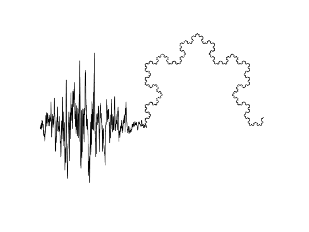

## *Fig.M5 (the neural mass model) *

#### *(J.M. Lina, M-C. Foti, 2024)*

## This code displays the results of the simulations a pair of oscillations (3 and 13 Hz) in one fBM (scale-free) backgroud (beta = 2.5 approx.).

#### The main reference: J. Dubé et al., *Rhythms and Background (RnB): the spectroscopy of sleep recordings*, 2024 

 
clc; clear; close all;
addpath('./ressources')
A = load('./data/Simu_2_oscillations','time','timeseries_1sf','beta');
B = load('./data/Simu_2_oscillations','time','neural_mass');
C = load('./data/Simu_2_oscillations.mat','log_fr','power');
f1 = make_fig1(A,B,C);

## Responses of wavelet-RnB (amplitude of the 3 and 13 Hz modes) 

 
addpath(genpath('./ressources'))
A = load('./data/Simu_2_oscillations','T13Hz','Amp_in');
B = load('./data/Simu_2_oscillations','T03Hz','Amp_in','Plin');
f2 = make_fig2(A,B);

## Estimation of the Hurst parameter (beta)

 
addpath(genpath('./ressources'))
A = load('./data/Simu_2_oscillations','beta','TBeta','Amp_in');
f3 = make_fig3(A);
